# Ackermann Steering Geometry Calculation and Plot

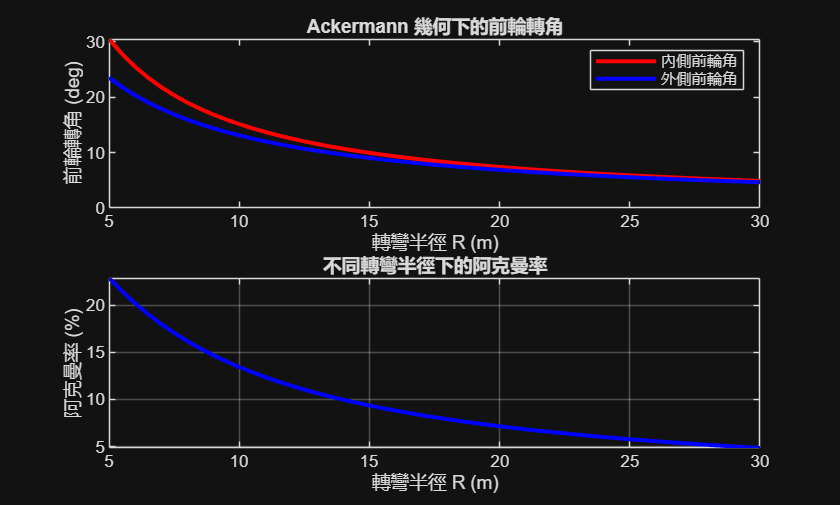

clear; clc;

% 車輛參數
L = 2.5;   % 軸距 (m)
W = 1.5;   % 前輪輪距 (m)

% 設定轉彎半徑範圍
R = 5:0.5:30;   % 從 5m 到 30m

% 計算內外前輪轉角
delta_i = atan(L ./ (R - W/2));   % 內側前輪角 (rad)
delta_o = atan(L ./ (R + W/2));   % 外側前輪角 (rad)

% 換算成角度
delta_i_deg = rad2deg(delta_i);
delta_o_deg = rad2deg(delta_o);

% 計算阿克曼率 (內外角差 / 內側角)
ackermann_rate = (delta_i_deg - delta_o_deg) ./ delta_i_deg * 100;

% 繪圖
figure;
subplot(2,1,1);
plot(R, delta_i_deg, 'r-', 'LineWidth', 2); hold on;
plot(R, delta_o_deg, 'b-', 'LineWidth', 2);
xlabel('轉彎半徑 R (m)');
ylabel('前輪轉角 (deg)');
legend('內側前輪角','外側前輪角');
title('Ackermann 幾何下的前輪轉角');

subplot(2,1,2);
plot(R, ackermann_rate, 'b-', 'LineWidth', 2);
xlabel('轉彎半徑 R (m)');
ylabel('阿克曼率 (%)');
title('不同轉彎半徑下的阿克曼率');
grid on;